clear all; clc;

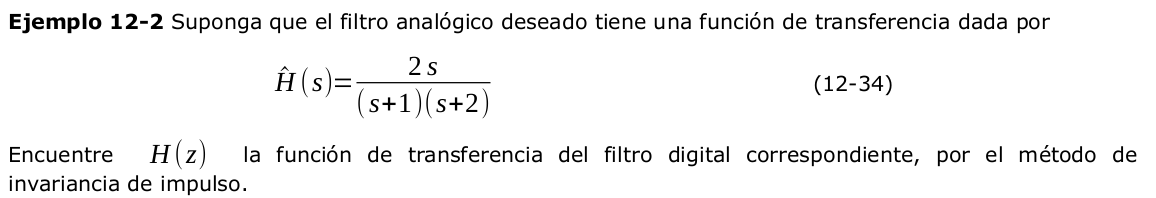


% función de transferencia - bessel
syms s;
H(s)=(2*s)/((s+1)*(s+2))

$$H(s) = \frac{2\,s}{\left(s+1\right)\,\left(s+2\right)}$$

% respuesta en frecuencia s
[B,A]=numden(H(s));
b= sym2poly(collect(B));
a= sym2poly(collect(A));
w=logspace(-1,1);
clf, freqs(b,a,w);

% H(s) en fracciones parciales
[r,p,k]=residue(b,a);
H(s) = sum(r(1:end)./(s-p(1:end)))

$$H(s) = \frac{4}{s+2}-\frac{2}{s+1}$$

% transformación invariante al impulso
syms z, syms T 'real';
HzT(z) = sum(r(1:end)./(1-exp(p(1:end)*T)*z^-1))

$$HzT(z) = \frac{2}{\frac{{\mathrm{e}}^{-T}}{z}-1}-\frac{4}{\frac{{\mathrm{e}}^{-2\,T}}{z}-1}$$



HzT(z)=collect(HzT(z),z^-1 )

$$HzT(z) = \frac{2\,{\mathrm{e}}^{3\,T}-\frac{4\,{\mathrm{e}}^{2\,T}-2\,{\mathrm{e}}^{T}}{z}}{{\mathrm{e}}^{3\,T}-\frac{{\mathrm{e}}^{2\,T}+{\mathrm{e}}^{T}}{z}+\frac{1}{z^{2}}}$$

% periodo de muestreo;
Hz(z)=subs(HzT(z),T=sym(1))

$$Hz(z) = -\frac{\frac{24.1197}{z}-40.1711}{\frac{1}{z^{2}}-\frac{10.1073}{z}+20.0855}$$

% respuesta en frecuencia
syms theta 'real';
clf; ezplot(10*log(abs(Hz(exp(j*theta)))),[0,pi]),
title('Magnitud en db'); grid on;

% respuesta en frecuencia
[Bz,Az]=numden(Hz(z));
bz=sym2poly(Bz); az=sym2poly(Az);
clf; freqz(bz, az)
